# Validation of Physics-Based Image Systems Simulation with 3D Scenes

## Figure 6

## 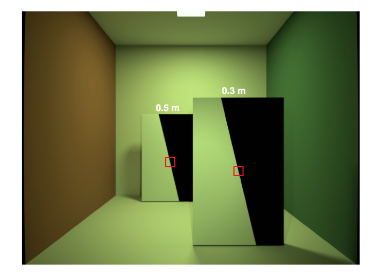

Fig. 6. The line spread function (LSF) was estimated from a simulated image the contained two slanted edges. These were positioned at two different depths (0.3 m and 0.5 m from the camera position) and field heights (0.7 mm and 0.8 mm) that matched the distances and field heights of the slanted edge target that was captured with the Google Pixel 4a camera. The LSF is estimated by selecting a small region of the slanted edge and using measurements from multiple rows to estimate a densely sampled step-edge response. The derivative of the step-edge response is the LSF. The modulation transfer function (MTF) is the magnitude of the Fourier Transform of the LSF.

### Initialize ISET and Docker

ieInit;
if ~piDockerExists, piDockerConfig; end

%% Create Cornell Box recipe
thisR = cbBoxCreate;

Read 1 materials.
Read 1 textures.
***Scene parsed.

Scene materials: CornellBoxReference
-------------------------------
             name        type
         ____________    ____

    1    BackWall        uber
    2    BottomWall      uber
    3    CubeLarge       uber
    4    CubeSmall       uber
    5    LeftWall        uber
    6    RightWall       uber
    7    ShieldMat       uber
    8    TopWall         uber
    9    areaLightMat    uber

-------------------------------
Assigned reflectance to: LeftWall
Assigned reflectance to: RightWall
Assigned reflectance to: BackWall
Assigned reflectance to: TopWall
Assigned reflectance to: BottomWall
Assigned reflectance to: CubeLarge
Assigned reflectance to: CubeSmall


### Add a distant light in front of box for visualization


distlight = piLightCreate('Dist light', 'type', 'spot',...
                    'spectrum spd', 'cbox-lights-1',...
                    'specscale', 0.001,...
                    'from', [0.008 0.15 -0.3],...
                    'to', [0.008 0.03 0],...
                    'cameracoordinate', false,...
                    'coneangle', 60,...
                    'conedeltaangle',50);
thisR.set('light', 'add', distlight);     

### Adjust the position of the camera


% The origin is in the bottom center of the box, the depth of the box is 
% 30 cm, the camera is 25 cm from the front edge. The position of the 
% camera should be set to 25 + 15 = 40 cm from the origin
from = thisR.get('from');
newFrom = [0 0.115 -0.40];% This is the place where we can see more
thisR.set('from', newFrom);
newTo = newFrom + [0 0 1]; % The camera is horizontal
thisR.set('to', newTo);

%% Remove cubes
thisR.set('assets', 'CubeSmall_B', 'chop');
thisR.set('assets', 'CubeLarge_B', 'chop');

%% Add slanted edge
assetTreeName = 'slantedbar';
slantedBar = piAssetLoad(assetTreeName);
piRecipeMerge(thisR, slantedBar.thisR, 'node name', slantedBar.mergeNode);

scale = thisR.get('asset', slantedBar.mergeNode, 'scale');
thisR.set('asset', slantedBar.mergeNode, 'scale', [0.08 0.13 0.01]*1.2);
% thisR.set('asset', slantedBar.mergeNode, 'world rotate', [0 0 180]);

thisR.set('asset', slantedBar.mergeNode, 'world position', [-0.04 0.08 0.10]);


% Now get a copy of the slanted bar and place it on a different position
[~, slantedBar2] = piObjectInstanceCreate(thisR, slantedBar.mergeNode);

thisR.set('asset', slantedBar2, 'world position', [0.05 0.08 -0.10]);

%% Specify rendering settings
% High resolution setting
thisR.set('film resolution',[4032 3024]/16); % Use [4032 3024] for high quality rendering
nRaysPerPixel = 256;% 1024 for high quality rendering
thisR.set('rays per pixel',nRaysPerPixel);
thisR.set('nbounces', 2);
thisR.set('fov', 77);
thisR.set('film diagonal', 7.056); % mm

%% Create lens
lensFile = fullfile(cboxRootPath, 'data', 'lens', 'pixel4a-rearcamera-ellipse-raytransfer.json');
cameraRTF = piCameraCreate('raytransfer','lensfile',lensFile);

camera = struct with fields:
            type: 'Camera'
         subtype: 'raytransfer'
    filmdistance: [1×1 struct]


thisR.camera = cameraRTF;

thisFilmDist = 0.57624; % in mm
thisR.set('film distance', thisFilmDist/1000);
piWrite(thisR);

Overwriting PBRT file /home/zhenglyu/git/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt


[oiTemp, result] = piRender(thisR, 'render type', 'radiance', 'scale illuminance', false,...
                        'docker image','vistalab/pbrt-v3-spectral:raytransfer-ellipse');

Docker container vistalab/pbrt-v3-spectral:raytransfer-ellipse
Docker command
	docker run -ti --rm --workdir="/home/zhenglyu/git/iset3d/local/CornellBoxReference" --volume="/home/zhenglyu/git/iset3d/local/CornellBoxReference":"/home/zhenglyu/git/iset3d/local/CornellBoxReference" vistalab/pbrt-v3-spectral:raytransfer-ellipse pbrt --outfile /home/zhenglyu/git/iset3d/local/CornellBoxReference/renderings/CornellBoxReference.dat /home/zhenglyu/git/iset3d/local/CornellBoxReference/CornellBoxReference.pbrt
*** Rendering time for CornellBoxReference:  19.5 sec ***

  Reading image h=189 x w=252 x 31 spectral planes.


oiName = sprintf(['CBRTF_slantedEdge_filmdist_' num2str(thisFilmDist) 'mm']);
oiSlantedBar = oiSet(oiTemp, 'name', oiName);

%% Sensor compute part
oi = oiSlantedBar;
sensor = cbSensorCreate;
sensor = sensorSetSizeToFOV(sensor, oiGet(oi, 'fov'), oi);
sensor = sensorSet(sensor, 'exp time', 0.1481);
sensor = sensorCompute(sensor, oi);

ip = cbIpCompute(sensor);

img = ipGet(ip, 'srgb');

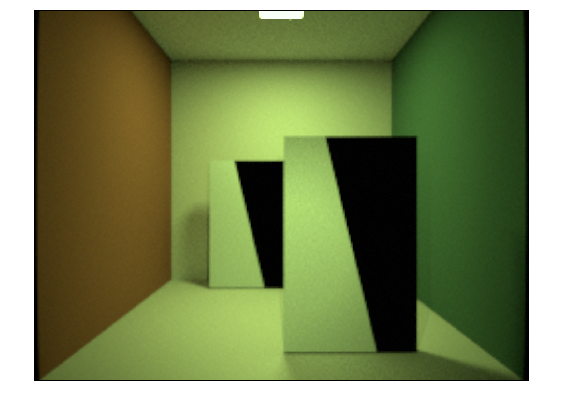

ieNewGraphWin; imagesc(img); axis off; truesize; % Low resolution image

## Figure 7

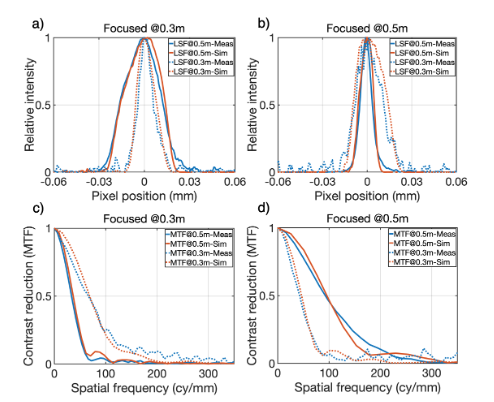

Fig. 7. Comparison of the spatial blur and depth of field. (a,b). The measured (blue) and simulated (red) LSFs are compared. The curves show the LSFs for lines at two different distances. Panel a shows data with a focal distance of 0.3m and Panel b with the focal distance of 0.5m. In each case the narrow LSF is for the line at the focal distance, and the broader LSF is for the line that is too near or too far. (c,d) The LSF data are transformed into the corresponding MTF curves where the broader MTF is for the line that is in focus. The measured and simulated lines were at slightly different field heights (0.7 mm and 0.8 mm), but this difference did not have a substantial impact on the measurements.